# FINAL EXAM Directory

This is a good starting point for exam 2 content. It gives an example of everything needed to run all the main functions we talked about. A good strat is using the help menu to access format

## Ch5 - Bracketing Roots

Basic root-finding

help bisect

 bisect: root location zeros
  [root,relErr,iter] = bisect(func,xl,xu,es,maxit,p1,p2,...)
  input:
    func = function handle (@)
    xl, xu = lower and upper guesses
    es = desired relative error (default = 0.0001%) (input %)
    maxit = maximum allowable iterations (default 50)
    p1,p2... = additional parameters used by func
  output:
    root = real root
    relErr = approximate relative error (%)
    iter = number of iterations



help falsepos

  falsepos: root location zeroes
  [root,froot,ea,iter]=falsepos(func,xl,xu,es,maxit,p1,p2,...):
  uses false position to find the root of func
  input:
    func = name of function
    xl, xu = lower and upper guesses
    es = desired relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by function
  output:
    root = root estimate
    froot = function at root estimate
    ea = approximate relative error (%)
    iter = number of iterations



help incsearch

  incsearch: incremental search root locator
  xb = incsearch(func,xmin,xmax,ns):
  finds brackets of x that contain sign changes
     of a function on an interval. Just moves left -> right, slow
  input:
    func = name of function
    xmin, xmax = endpoints of interval
    ns = number of subintervals (default = 50)
  output:
    xb(k,1) is the lower bound of the kth sign change
    xb(k,2) is the upper bound of the kth sign change
  If no brackets found, xb = [].



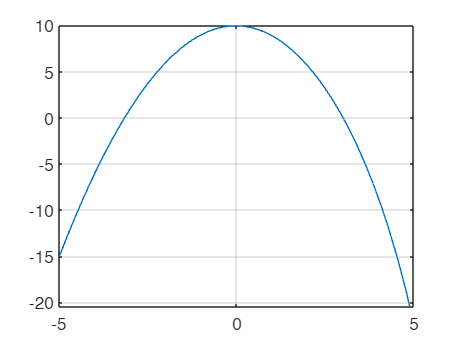


% Write inline function & check w/ plotting
func = @(x) -x.^2 - 1/20*exp(x)+10;
fplot(func,[-5 5]);
hold off; grid on;


% Bisection Method
%   Splits in half over and over. Keeps sign change interval
xl = 0; xu = 5; 
[root,relErr,iter] = bisect(func,xl,xu)

root = 2.9994

relErr = 7.9489e-05

iter = 21


% False Position
%   Two points, line through, find intersect, use next
%   Can be hurt by shape, best if close to linear
[root_FP,froot,ea,iter]=falsepos(func,xl,xu)

root_FP = 2.9994

froot = 4.8513e-06

ea = 3.8469e-05

iter = 16


% Incremental search method
%   Splits into evenly spaced chunks. Trouble if too wide.
%   Should hit all the roots
xb = incsearch(func,xl,xu,1000) % shows what brackets the sign change

number of root brackets:
     1



xb =     2.9980    3.0030


## Ch6 - Open Methods

Finding the roots of functions (quadratic often)

help fixpt

  fixpt: fixed point iteration root locator
  [x1,ea,iter] = fixpt(g,x0,es,maxit)
  This function determines the root of x = g(x) with fixed
  The method is repeated until either the percent relative
  is equal to or less than es (default:1.e–6) or the number
  exceeds maxit (default:50).
  Input:
    g = the function for g(x)
    x0 = initial guess for x
    es = relative error stopping criterion (%)
    maxit = maximum number of iterations
  Output:
    x1 = solution estimate
    ea = relative error
    iter = number of iterations
 {



help newtraph

  newtraph: Newton-Raphson root location zeroes
  [root,ea,iter]=newtraph(func,dfunc,xr,es,maxit,p1,p2,...):
  uses Newton-Raphson method to find the root of func
  input:
    func = name of function
    dfunc = name of derivative of function
    xr = initial guess
    es = desired relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by function
  output:
    root = real root
    ea = approximate relative error (%)
    iter = number of iterations



help secant

 xr=secant(f,x1,x2,tol,maxIt)
 
 Implements the Secant Method
 
    f = function to find the root of
    x1 = first x value
    x2 = second x value
    tol = stopping criteria tolerance
    maxIt = maximum number of iterations
    xr = found root
 
 ABH
 Spring 2023



help modSecant

 xr=modSecant(f,x,delta,tol,maxIt)
 
 Implements the modified secant method
 
  f = function to find the root of
  x0 = initial value
  delta = value of delta
  tol = stopping criteria tolerance
  maxIt = maximum number of iterations
  xr = found root
 
 ABH
 Spring 2023



help roots

 roots  Find polynomial roots.
    roots(C) computes the roots of the polynomial whose coefficients
    are the elements of the vector C. If C has N+1 components,
    the polynomial is C(1)*X^N + ... + C(N)*X + C(N+1).
 
    Note:  Leading zeros in C are discarded first.  Then, leading relative
    zeros are removed as well.  That is, if division by the leading
    coefficient results in overflow, all coefficients up to the first
    coefficient where overflow occurred are also discarded.  This process is
    repeated until the leading coefficient is not a relative zero.
 
    Class support for input c: 
       float: double, single
 
    See also poly, residue, fzero.

    Documentation for roots
    

help polyval

 polyval Evaluate polynomial.
    Y = polyval(P,X) returns the value of a polynomial P evaluated at X. P
    is a vector of length N+1 whose elements are the coefficients of the
    polynomial in descending powers:
 
        Y = P(1)*X^N + P(2)*X^(N-1) + ... + P(N)*X + P(N+1)
 
    The polynomial P is evaluated at all points in X. See POLYVALM for
    evaluation of a polynomial P in a matrix sense.
 
    [Y,DELTA] = polyval(P,X,S) uses the optional output structure S created
    by POLYFIT to generate prediction error estimates DELTA. DELTA is an
    estimate of the standard deviation of the error in predicting a future
    observation at X by P(X).
 
    If the coefficients in P are least squares estimates computed by
    POLYFIT, and the errors in the data input to POLYFIT are independent,
    normal, with constant variance, then Y +/- DELTA will contain at least
    50% of future observations at X.
 
    Y = polyval

help fzero

 fzero  Single-variable nonlinear zero finding. 
    X = fzero(FUN,X0) tries to find a zero of the function FUN near X0, 
    if X0 is a scalar.  It first finds an interval containing X0 where the 
    function values of the interval endpoints differ in sign, then searches 
    that interval for a zero.  FUN is a function handle.  FUN accepts real 
    scalar input X and returns a real scalar function value F, evaluated 
    at X. The value X returned by fzero is near a point where FUN changes 
    sign (if FUN is continuous), or NaN if the search fails.  
 
    X = fzero(FUN,X0), where X0 is a vector of length 2, assumes X0 is a 
    finite interval where the sign of FUN(X0(1)) differs from the sign of 
    FUN(X0(2)). An error occurs if this is not true.  Calling fzero with a
    finite interval guarantees fzero will return a value near a point where
    FUN changes sign.
 
    X = <


% Fixed Point Iteration
%   Uses g(x) = x
%   Need [a b], [a b] to guarantee convergence
%   Note: I did make an automatic g finder version...
g = @(x) sqrt(-1/20*exp(x)+10);
x0 = 4; % initial guess
[x1_fixpt,ea,iter] = fixpt(g,x0)

x1_fixpt = 2.9994

ea = 1.7710e-07

iter = 12


% Newton-Raphson
%   Uses derivative
dfunc = @(x)-2*x - 1/20*exp(x); % deriv
xr = x0;
[root_nr,ea,iter]=newtraph(func,dfunc,xr) % 5 iter = fast

root_nr = 2.9994

ea = 8.9909e-10

iter = 5


% Secant
%   Avoid need for deriv - bckwd finite divided dif
xr=secant(func,xl,xu)

xr = 2.9994


% modSecant
%   Uses a delta (kinda like inc search)
delta = 0.001;
xr_ms = modSecant(func,x0,delta)

xr_ms = 2.9994

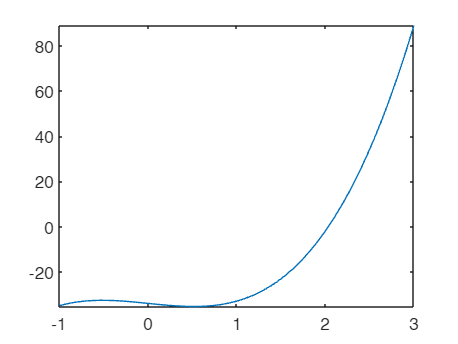


% Roots
%   Find roots given polynomial coeff in row vector
pfunc = @(x) 5*x.^3-4*x-34;
fplot(pfunc,[-1 3])

C = [5 0 -4 -34];
xr_roots = roots(C)

xr_roots =    2.0351 + 0.0000i
  -1.0175 + 1.5186i
  -1.0175 - 1.5186i


p = poly(xr_roots)

p =     1.0000    0.0000   -0.8000   -6.8000


pv = polyval(C,x0) % evaluate for coeffs C at x0

pv = 270


% fzero
%   *** This is the one that really is versatile, universal ***
xr_fz = fzero(func, x0)

xr_fz = 2.9994

xr_fzbr = fzero(func, [0 5])

xr_fzbr = 2.9994

## Ch7 - Optimization

Finding the mins & maxes of functions (2D and 3D, multivariable)

help goldmin

  goldmin: minimization golden section search
  [x,fx,ea,iter]=goldmin(f,xl,xu,es,maxit,p1,p2,...):
  uses golden section search to find the minimum of f
  input:
    f = name of function
    xl, xu = lower and upper guesses
    es = desired relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by f
  output:
    x = location of minimum
    fx = minimum function value
    ea = approximate relative error (%)
    iter = number of iterations
  Can find max w/ g(x) = -f(x) -> max of f(x) = -g(x)



help fsolve

 fsolve solves systems of nonlinear equations of several variables.
 
    fsolve attempts to solve equations of the form:
              
    F(X) = 0    where F and X may be vectors or matrices.   
 
    fsolve implements three different algorithms: trust region dogleg,
    trust region, and Levenberg-Marquardt. Choose one via the option
    Algorithm: for instance, to choose trust region, set OPTIONS =
    optimoptions('fsolve','Algorithm','trust-region'), and then pass
    OPTIONS to fsolve.
     
    X = fsolve(FUN,X0) starts at the matrix X0 and tries to solve the 
    equations in FUN.  FUN accepts input X and returns a vector (matrix) of 
    equation values F evaluated at X. 
 
    X = fsolve(FUN,X0,OPTIONS) solves the equations with the default
    optimization parameters replaced by values in OPTIONS, an argument
    created with the OPTIMOPTIONS function.  See OPTIMOPTIONS fo

help fminsearch

 fminsearch Multidimensional unconstrained nonlinear minimization (Nelder-Mead).
    X = fminsearch(FUN,X0) starts at X0 and attempts to find a local minimizer 
    X of the function FUN.  FUN is a function handle.  FUN accepts input X and 
    returns a scalar function value F evaluated at X. X0 can be a scalar, vector 
    or matrix.
 
    X = fminsearch(FUN,X0,OPTIONS)  minimizes with the default optimization
    parameters replaced by values in the structure OPTIONS, created
    with the OPTIMSET function.  See OPTIMSET for details.  fminsearch uses
    these options: Display, TolX, TolFun, MaxFunEvals, MaxIter, FunValCheck,
    PlotFcns, and OutputFcn.
 
    X = fminsearch(PROBLEM) finds the minimum for PROBLEM. PROBLEM is a
    structure with the function FUN in PROBLEM.objective, the start point
    in PROBLEM.x0, the options structure in PROBLEM.options, and solver
    name 'fminsearch' in PROB

help fminbnd

 fminbnd Single-variable bounded nonlinear function minimization.
    X = fminbnd(FUN,x1,x2) attempts to find  a local minimizer X of the function 
    FUN in the interval x1 < X < x2.  FUN is a function handle.  FUN accepts 
    scalar input X and returns a scalar function value F evaluated at X.
 
    X = fminbnd(FUN,x1,x2,OPTIONS) minimizes with the default optimization
    parameters replaced by values in the structure OPTIONS, created with
    the OPTIMSET function. See OPTIMSET for details. fminbnd uses these
    options: Display, TolX, MaxFunEval, MaxIter, FunValCheck, PlotFcns, 
    and OutputFcn.
 
    X = fminbnd(PROBLEM) finds the minimum for PROBLEM. PROBLEM is a
    structure with the function FUN in PROBLEM.objective, the interval
    in PROBLEM.x1 and PROBLEM.x2, the options structure in PROBLEM.options,
    and solver name 'fminbnd' in PROBLEM.solver. 
 
    [X,FVAL] = fminbnd</

help meshgrid

 meshgrid   Cartesian rectangular grid in 2-D or 3-D
    [X,Y] = meshgrid(x,y) returns 2-D grid coordinates based on the
    coordinates contained in vectors x and y. X is a matrix where each row
    is a copy of x, and Y is a matrix where each column is a copy of y. The
    grid represented by the coordinates X and Y has length(y) rows and
    length(x) columns.
 
    [X,Y,Z] = meshgrid(x,y,z) returns 3-D grid coordinates defined by the
    vectors x, y, and z. The grid represented by X, Y, and Z has size
    length(y)-by-length(x)-by-length(z).
 
    [X,Y] = meshgrid(x) is the same as [X,Y] = meshgrid(x,x), returning
    square grid coordinates with grid size length(x)-by-length(x).
 
    [X,Y,Z] = meshgrid(x) is the same as [X,Y,Z] = meshgrid(x,x,x),
    returning 3-D grid coordinates with grid size
    length(x)-by-length(x)-by-length(x).
 
    meshgrid

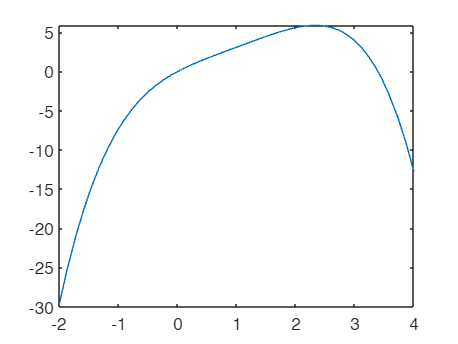


f = @(x) 4*x-1.8*x^2+1.2*x^3-0.3*x^4;
xl = -2; xu = 4; es = 1;
fplot(f,[xl xu])


% minimum goldmin
[xmin,fx,ea,iter]=goldmin(f,xl,xu)

xmin = -2.0000

fx = -29.5999

ea = 9.9656e-05

iter = 30


% maximum
%   Find the min of -1*f(x)
g = @(x) -1*f(x); % just flip upside down
[xmax,fx,ea,iter]=goldmin(g,xl,xu)

xmax = 2.3264

fx = -5.8853

ea = 8.5676e-05

iter = 30


%  fsolve
X = fsolve(f,3)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


X = 3.3903


% fminbnd
%   Most robust, builtin Matlab min/max finder
Xmin = fminbnd(f,xl,xu) % This is the most robust way**** 

Xmin = -1.9999

Xmax = fminbnd(g,xl,xu)

Xmax = 2.3264

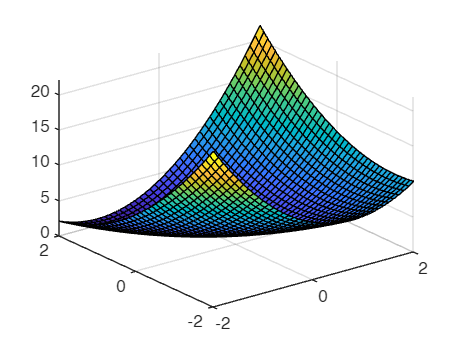


% fminsearch
%   Use for 3D cases
%   Define vars as x(1), x(2)...
g = @(x) 2+x(1)-x(2)+2*x(1)^2+2*x(1)*x(2)+x(2)^2;

[x1, x2] = meshgrid(-2:0.1:2, -2:0.1:2);
G = 2 + x1 - x2 + 2*x1.^2 + 2*x1.*x2 + x2.^2;
figure;
surf(x1, x2, G);


X = fminsearch(g,[0 0])

X =    -1.0000    1.5000



% fsolve
% Define the system of nonlinear equations
F = @(v) [v(1)^2 + v(2)^2 - 10;   % Equation 1
          exp(v(1)) + v(2) - 1];  % Equation 2

% Initial guess for [x, y]
x0 = [1; 1];

% Solve using fsolve
x_sol = fsolve(F, x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x_sol =    -3.0159
    0.9510


## Ch8 - Linear Algebra

% Solve a linear system
A = [1 2 3; 4 7 6; 9 8 7];
b = [13; 48; 97];
C = A\b

C =     9.5000
    1.0000
    0.5000



% Transpose & Inverse
Ctrans = C'

Ctrans =     9.5000    1.0000    0.5000


Ainv = inv(A) % must be square

Ainv =    -0.0250   -0.2500    0.2250
   -0.6500    0.5000   -0.1500
    0.7750   -0.2500    0.0250


I = eye(size(A))

I =      1     0     0
     0     1     0
     0     0     1



% Matrix mult
ABmm = A*b

ABmm =          400
         970
        1180


## Ch12 - Iterative Methods

Solves a system of equations [A]{x}={b}

help GaussSeidel

  GaussSeidel: Gauss Seidel method for solving a system of linear equations [A]{x}={b}
  [x,ea,iter] = GaussSeidel(A,b,es,maxit): Gauss Seidel without relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



help GaussSeidelRelax

  GaussSeidelRelax: Gauss Seidel method with relaxation
  [x,ea,iter] = GaussSeidelRelax(A,b,lambda,es,maxit): Gauss Seidel with relaxation
  input:
  A = coefficient matrix
  b = right hand side vector
  lambda = relation factor (default = 1)
  es = stop criterion (default = 0.00001%)
  maxit = max iterations (default = 50)
  output:
  x = solution vector
  ea = maximum relative error (%)
  iter = number of iterations



help newtmult 

  newtmult: Newton-Raphson root zeroes nonlinear systems
  [x,f,ea,iter]=newtmult(func,x0,es,maxit,p1,p2,...):
  [x,f,ea,iter]=newtmult(@jfreact2,x0); [have u&v w/ ftns]
  uses the Newton-Raphson method to find the roots of
  a system of nonlinear equations
  input:
    func = name of function that returns f and J
    x0 = initial guess
    es = desired percent relative error (default = 0.0001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by function
  output:
    x = vector of roots
    f = vector of functions evaluated at roots (residual, ~ 0)
    ea = approximate percent relative error (%)
    iter = number of iterations



help jfreact2 

  jfreact2: Calculates the Jacobian matrix J and the function vector f
            for a system of two nonlinear equations, f1(x1, x2) and f2(x1, x2).
  Notes added prior to the exam:
  NOTE: This specific implementation uses the finite-difference approximation
        for partial derivatives and assumes the system is defined by two
        external functions, u(x1, x2) and v(x1, x2), where f1=u and f2=v.
 
  input:
    x = current root estimate vector [x1; x2]
    varargin = optional parameters to pass to u and v functions (not used here)
 
  output:
    J = The 2x2 Jacobian matrix of partial derivatives
    f = The 2x1 function vector [f1; f2]
 
  -------------------------------------------------------------------------
  THE JACOBIAN MATRIX (J) STRUCTURE:
 
  J = [ df1/dx1, df1/dx2 ]   -> The first row is the gradient of f1
      [ df2/dx1, df2/dx2 ]   -> The second row is the gradient of f2
  -------------------------------------------------------------------------

help u % used in jfreact2 and newtmult

  u: fu = u(x1,x2)
    This is required for a poorly written newtmult code. 
    Have to pass in like this instead of as parameters.



help v % used in jfreact2 and newtmult

  v: fu = v(x1,x2)
    This is required for a poorly written newtmult code. 
    Have to pass in like this instead of as parameters.




% Gauss Seidel
%   Solves linear system of eq A\b
%   Needs diagonal dominance
%   Only really useful for mega large sparse systems (A\b better)
% Bad Gauss Seidel bc A not DD and can't be
[x_GS,ea,iter] = GaussSeidel(A,b) % diverges bc not diag dom

x_GS = 1.0e+26 *

    2.2123
   -0.7614
   -1.9743


ea = 70.2868

iter = 50


A_ddNo = [A(3,:); A(2,:); A(1,:)]; % mag along diag > mag not diag
b = [b(3); b(2); b(1)];
[x_GS_bet,ea,iter] = GaussSeidel(A_ddNo,b) % closer to DD, but not guarant

x_GS_bet =     9.5000
    1.0000
    0.5000


ea = 9.2670e-06

iter = 34

CC_check1 = A_ddNo\b

CC_check1 =     9.5000
    1.0000
    0.5000



% A_dd
A_dd = [5 2 1; 4 11 6; 9 8 18]; % new
[x_GS_dd,ea,iter] = GaussSeidel(A_dd,b)

x_GS_dd =    20.4312
    2.7883
  -10.7326


ea = 2.6775e-06

iter = 17

C_check = A_dd\b

C_check =    20.4312
    2.7883
  -10.7326




% Gauss Seidel Relax
%   Uses lambda for relaxation factor
%     0 < lambda < 1 (Underrelaxation): Used for non-convergent or unstable systems to dampen oscillations and improve stability.
%   - 1 < lambda <= 2 (Overrelaxation/Successive Over-Relaxation - SOR): Used to accelerate convergence for systems that already converge.

lambda = 0.4; % underrelax: slower to /> chance converge
[x_UR,ea,iter_UR] = GaussSeidelRelax(A,b,lambda) % still didn't work up to 0.01

x_UR = 1.0e+11 *

    4.6944
   -0.5024
   -3.5161


ea = 36.8853

iter_UR = 50



lambda = 1.2; % overrelax: slower to /> chance converge
[x_OR,ea,iter_OR] = GaussSeidelRelax(A_dd,b,lambda) % cut iter in half. 1.6 too much

x_OR =    20.4312
    2.7883
  -10.7326


ea = 5.4365e-06

iter_OR = 22



% Newtmult
%   finds roots of nonlinear system
%   Need Jacobian
%   Put ftns in u, v, ...
x0 = [2 3.5];
[x,f,ea,iter]=newtmult(@jfreact2,x0) 

x =     1.3721    2.8721
    0.2395    1.7395


f = 1.0e-06 *

   -0.0064
   -0.2814


ea = 1.0e-04 *

    0.1316    0.0181


iter = 5


% can doublecheck with fsolve
%F = [@ [u stuff]; @ [v stuff];
%x = fsolve(F, x0)

# Exam 3 Directory - [Move]

This is a good starting point for exam 2 content. It gives an example of everything needed to run all the main functions we talked about. A good strat is using the help menu to access format

## Ch 13 - Eigenvalues

[A-lamda*I]{x} = 0 -> det(A-lamda*I) -> find lamda

Applicable to 2nd order diff eqs.

help eig

 eig    Eigenvalues and eigenvectors.
    E = eig(A) produces a column vector E containing the eigenvalues of 
    a square matrix A.
 
    [V,D] = eig(A) produces a diagonal matrix D of eigenvalues and 
    a full matrix V whose columns are the corresponding eigenvectors  
    so that A*V = V*D.
  
    [V,D,W] = eig(A) also produces a full matrix W whose columns are the
    corresponding left eigenvectors so that W'*A = D*W'.
 
    [...] = eig(A,"nobalance") performs the computation with balancing
    disabled, which sometimes gives more accurate results for certain
    problems with unusual scaling. If A is symmetric, eig(A,"nobalance")
    is ignored since A is already balanced.
 
    [...] = eig(A,"balance") is the same as eig(A).
 
    E = eig(A,B) produces a column vector E containing the generalized 
    eigenvalues of square ma

help powereig

  powereig - Computes the dominant eigenvalue and eigenvector using the Power Method
 
  Syntax:
    [eigval, eigvect] = powereig(A, es, maxit)
 
  Inputs:
    A     - Square matrix for which the dominant eigenvalue/vector is sought
    es    - Desired relative error tolerance (stopping criterion, e.g. 0.0001)
    maxit - Maximum number of iterations to perform
 
  Outputs:
    eigval  - Dominant (largest magnitude) eigenvalue of A
    eigvect - Corresponding normalized eigenvector
 
  Example:
    A = [4 1; 2 3];
    [eigval, eigvect] = powereig(A, 0.0001, 100)
 
  Description:
    This function implements the Power Method, an iterative algorithm used 
    to find the largest eigenvalue (in magnitude) and its associated eigenvector.
    The algorithm repeatedly multiplies an arbitrary vector by the matrix A,
    normalizes the result, and estimates convergence based on the change in eigenvalue.
 
  Note: Finding the smallest eigenvalue
    The smallest eigenvalue and its associated ei

help solve_ode_system

  ANALYZE_ODE_SYSTEM_VARIABLES Solves a 2x2 linear system x' = Ax.
    This function calculates the eigenvalues and eigenvectors, classifies the 
    system type (e.g., Undamped, Overdamped), and generates the final 
    symbolic displacement equation y(t) = x1(t).
    function [y_eq, type, evals, v1, v2] = solve_ode_system(A)
 
  Inputs:
    A: The 2x2 coefficient matrix [0 1; -k/m -c/m]
 
  Outputs:
    system_type: Classification string (e.g., 'Pure Oscillation (Undamped)')
    evals_str:   Formatted string of the two eigenvalues (L1 and L2)
    evec1_str:   Formatted string of the first eigenvector (v1)
    evec2_str:   Formatted string of the second eigenvector (v2)
    y_eq_str:    Symbolic equation for the displacement y(t)




A = [10 -5; -5 10];
[v,lamda] = eig(A) % v = eigenvectors (lamda plugged in -> set = 0)

v =    -0.7071   -0.7071
   -0.7071    0.7071


lamda =      5     0
     0    15



% Needs work:
%   - Setting up the matrixes from the diff eq
%       * x1 = y, x2 = y' = x1', x3 = y'' = x2', x4 = y''' = x3'
%       * x1' = x2; x2' = x3, x3' = [solve for y''' (or the largest)]
%       * x' = A*x form
%       * A = [0 1 0; 0 0 1; # # #]

% Example
%   y''' - 4y'' + 6y' - 3y = 0
%       * x1 = y, x1' = x2 = y', x2' = x3 = y'', x3' = x4 = y'''
%       * x3' = 4x3 - 6x2 + 3x1
%       * x' = A*x, x = [x1 x2 x3]'
B = [0 1 0; 0 0 1; 3 -6 4]; % go up from x1 to x3 to match x vector
[v1,lamda1] = eig(B)

v1 =   -0.5774 + 0.0000i   0.1387 - 0.2402i   0.1387 + 0.2402i
  -0.5774 + 0.0000i   0.4160 - 0.2402i   0.4160 + 0.2402i
  -0.5774 + 0.0000i   0.8321 + 0.0000i   0.8321 + 0.0000i


lamda1 =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.5000 + 0.8660i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.5000 - 0.8660i



% Powereig
es = 0.001; 
[eigval, eigvect] = powereig(B, es)

eigval = 1

eigvect =      1
     1
     1


% normalized eigenvector bc the highest one always set to 1

% we can normalize v1 to doublecheck
Vnorm = v1./max(v1)

Vnorm =    1.0000 + 0.0000i   0.1667 - 0.2887i   0.1667 + 0.2887i
   1.0000 + 0.0000i   0.5000 - 0.2887i   0.5000 + 0.2887i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i



% Find the smallest eigenvector
[eigvalSmall, eigvectSmall] = powereig(inv(B), es)

eigvalSmall = 1

eigvectSmall =      1
     1
     1




% Polynomial method -> characteristic equation
%   Wild, not sure how it works fully
%   Uses the characteristic polynomial
help poly

 poly Convert roots to polynomial.
    poly(A), when A is an N by N matrix, is a row vector with
    N+1 elements which are the coefficients of the
    characteristic polynomial, det(lambda*eye(size(A)) - A).
 
    poly(V), when V is a vector, is a vector whose elements are
    the coefficients of the polynomial whose roots are the
    elements of V. For vectors, ROOTS and poly are inverse
    functions of each other, up to ordering, scaling, and
    roundoff error.
 
    Examples:
 
    roots(poly(1:20)) generates Wilkinson's famous example.
 
    Class support for inputs A,V:
       float: double, single
 
    See also roots, conv, residue, polyval.

    Documentation for poly
    

p = poly(B) % when A is square, poly(A) = coefficients of characteristic poly

p =     1.0000   -4.0000    6.0000   -3.0000


%           aka coeff of det(lamda*eye(size(A)-A)
d = roots(p) % eigenvalues based off the characteristic polynomial

d =    1.5000 + 0.8660i
   1.5000 - 0.8660i
   1.0000 + 0.0000i



% solve_ode_system
%   * Chat code designed to interpret stuff after A is found. Should do
%   everything. Prob don't use on the exam

## Ch 14 - Linear Regression

#### Stats Basics

help var

 var Variance.
    For vectors, Y = var(X) returns the variance of the values in X.  For
    matrices, Y is a row vector containing the variance of each column of
    X.  For N-D arrays, var operates along the first non-singleton
    dimension of X.
 
    var normalizes Y by N-1 if N>1, where N is the sample size.  This is
    an unbiased estimator of the variance of the population from which X is
    drawn, as long as X consists of independent, identically distributed
    samples. For N=1, Y is normalized by N. 
 
    Y = var(X,1) normalizes by N and produces the second moment of the
    sample about its mean.  var(X,0) is the same as var(X).
 
    Y = var(X,W) computes the variance using the weight vector W.  W 
    typically contains either counts or inverse variances.  The length of W 
    must equal the length of the dimension over which v

help std

 std Standard deviation.
    For vectors, Y = std(X) returns the standard deviation.  For matrices,
    Y is a row vector containing the standard deviation of each column.  For
    N-D arrays, std operates along the first non-singleton dimension of X.
 
    std normalizes Y by N-1 if N>1, where N is the sample size.  This is
    the sqrt of an unbiased estimator of the variance of the population
    from which X is drawn, as long as X consists of independent,
    identically distributed samples. For N=1, Y is normalized by N.
 
    Y = std(X,1) normalizes by N and produces the square root of the second
    moment of the sample about its mean.  std(X,0) is the same as std(X).
 
    Y = std(X,W) computes the standard deviation using the weight vector W.
    W typically contains either counts or inverse variances.  The length of
    W must equal the lengt

help hist

 hist  Histogram.
    hist is not recommended. Use HISTOGRAM or HISTCOUNTS instead.
  
    N = hist(Y) bins the elements of Y into 10 equally spaced containers
    and returns the number of elements in each container.  If Y is a
    matrix, hist works down the columns.
 
    N = hist(C) returns the category counts for the categorical array C.
    For a categorical matrix, hist works down the columns of Y and returns
    a matrix of counts with one column for each column of Y and one row for
    each category.
 
    N = hist(Y,M), where M is a scalar, uses M bins.
 
    N = hist(Y,X), where X is a vector, returns the distribution of Y among
    bins with centers specified by X. The first bin includes data between
    -inf and the first center and the last bin includes data between the
    last bin and inf. Note: Use HISTC if it is more natural to specif

help histcounts

 histcounts - Histogram bin counts
    This MATLAB function partitions the X values into bins and returns the
    bin counts and the bin edges.

    Syntax
      [N,edges] = histcounts(X)
      [N,edges] = histcounts(X,nbins)
      [N,edges] = histcounts(X,edges)
      [N,edges,bin] = histcounts(___)

      N = histcounts(C)
      N = histcounts(C,Categories)
      [N,Categories] = histcounts(___)

      [___] = histcounts(___,Name,Value)

    Input Arguments
      X - Data to distribute among bins
        vector | matrix | multidimensional array
      C - Categorical data
        categorical array
      


A = [29.65 28.55 28.65 30.15 29.35 29.75 29.25 ...
    30.65 28.15 29.85 29.05 30.25 30.85 28.75 ...
     29.65 30.45 29.15 30.45 33.65 29.35 29.75 ... 
     31.25 29.45 30.15 29.65 30.55 29.65 29.25]; % row vector best

mean_p = mean(A)

mean_p = 29.8321

med_p = median(A)

med_p = 29.6500

mod = mode(A)

mod = 29.6500

% [M,F] = mode(A) % FAILS if multimodal: only designed for having 1 mode - use hist instead
rang = range(A)

rang = 5.5000

rang_2 = max(A)-min(A)

rang_2 = 5.5000

stdDev = std(A)

stdDev = 1.0453

varA = var(A)

varA = 1.0926

cv = varA./mean_p*100 % percent

cv = 3.6626

s = size(A)

s =      1    28


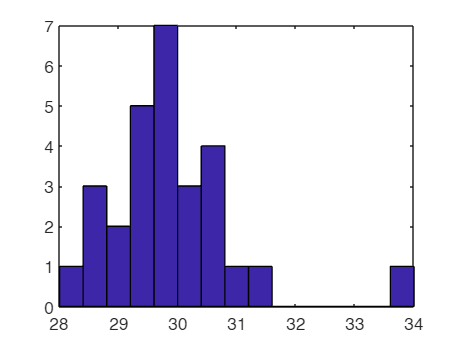


% histogram
binmids = [28.2:0.4:33.8];
figure;
hist(A,binmids) % no arguments, it makes a histogram

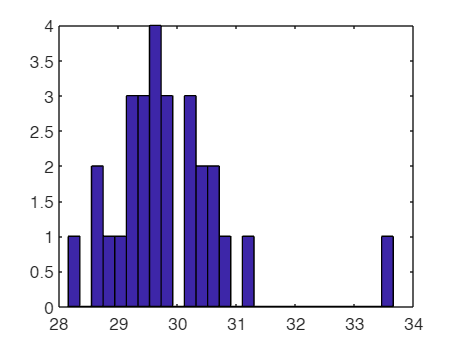

figure;
hist(A, s(2))
hold off;


[N,edges] = histcounts(A, s(2))

N =      1     0     2     1     1     3     3     4     3     0     3     2     2     1     0     1     0     0     0     0     0     0     0     0     0     0     0     1


edges =    28.1000   28.2990   28.4980   28.6970   28.8960   29.0950   29.2940   29.4930   29.6920   29.8910   30.0900   30.2890   30.4880   30.6870   30.8860   31.0850   31.2840   31.4830   31.6820   31.8810   32.0800   32.2790   32.4780   32.6770   32.8760   33.0750   33.2740   33.4730   33.6720


#### Linear Regression Basics

help linregr

  linregr: linear regression curve fitting
    [a, r2] = linregr(x,y): Least squares fit of straight
    line to data by solving the normal equations
  input:
    x = independent variable
    y = dependent variable
  output:
    a = vector of slope, a(1), and intercept, a(2)
    r2 = coefficient of determination
 
  linearization help:
    y = alph * exp(beta*x)
        ln(y) = ln(alph) + beta*x 
            Note: use log() in MATLAB
        [a, r2] = linregr(x, log(y));
        alpha = exp(a(2));
        beta  = a(1);
 
    y = alph * x^beta
        log10(y) = log10(alph) + beta*log10(x)
        [a, r2] = linregr(log10(x), log10(y));
        alpha = 10^(a(2));
        beta  = a(1);
 
    y = alph * x/(beta + x)
        1/y = 1/alph + (beta/alph)*(1/x)
          (linear in 1/x)
        [a, r2] = linregr(1./x, 1./y);
        alpha = 1 / a(2);
        beta  = a(1) / a(2);



help linregrzero

  linregrzero: linear regression curve fitting with zero intercept
    [a, r2] = linregr(x,y): Least squares fit of straight
    line to data with zero intercept
  input:
    x = independent variable
    y = dependent variable
  output:
    a1 = slope



help fitlm

 fitlm Create linear regression model by fitting to data.
    LM = fitlm(TBL) fits a linear model LM to the data in the table/dataset
    TBL, treating the last column as the response variable.
 
    LM = fitlm(TBL,Y) fits a linear model LM to the data in TBL, using Y as
    the response variable. Y must be a double or single vector with the
    same number of rows as TBL.
 
    LM = fitlm(TBL,VARNAME) fits a linear model LM to the data TBL, using
    the variable name given by VARNAME as the response variable. VARNAME 
    must be a string scalar or character vector of a variable in TBL.
 
    LM = fitlm(__,MODELSPEC) fits the model specified by MODELSPEC to
    variables in TBL, and returns the linear model LM. MODELSPEC can be any 
    of the following:
 
        'linear'            Linear (main effect) terms only.
        'interactions'      Linear and pairwise interaction terms.
        'purequadr

help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
    rsquared -  Coefficient of determination or (unadjusted) R-squared
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit

help polyval

 polyval Evaluate polynomial.
    Y = polyval(P,X) returns the value of a polynomial P evaluated at X. P
    is a vector of length N+1 whose elements are the coefficients of the
    polynomial in descending powers:
 
        Y = P(1)*X^N + P(2)*X^(N-1) + ... + P(N)*X + P(N+1)
 
    The polynomial P is evaluated at all points in X. See POLYVALM for
    evaluation of a polynomial P in a matrix sense.
 
    [Y,DELTA] = polyval(P,X,S) uses the optional output structure S created
    by POLYFIT to generate prediction error estimates DELTA. DELTA is an
    estimate of the standard deviation of the error in predicting a future
    observation at X by P(X).
 
    If the coefficients in P are least squares estimates computed by
    POLYFIT, and the errors in the data input to POLYFIT are independent,
    normal, with constant variance, then Y +/- DELTA will contain at least
    50% of future observations at X.
 
    Y = polyval

#### Transformations

x = (0:0.5:5)';                 
y = 2.5 * exp(0.4 * x)+ 0.2*cos(x); % just added a slight jitter

figure;
[badFit_a badFit_r2] = linregr(x,y) % clearly doesn't look linear

badFit_a =     3.0034    0.7069


badFit_r2 = 0.9168

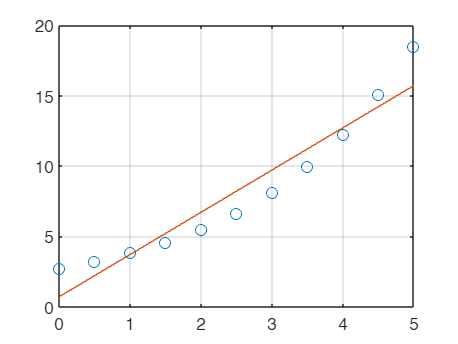

hold off;


% linearize **** y = alph*exp(beta*x)
figure;
[a, r2] = linregr(x,log(y))

a =     0.3859    0.9581


r2 = 0.9986

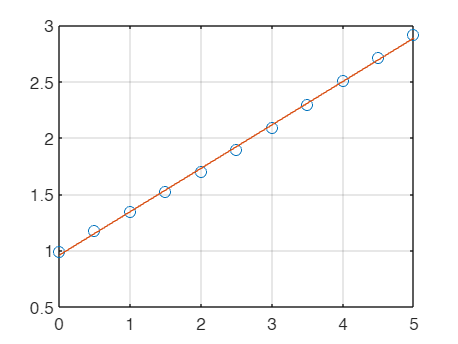

hold off;

alph = exp(a(2))

alph = 2.6067

beta = a(1)

beta = 0.3859

yp = alph*exp(beta*x);
plot(x,y,'o'); hold on;
plot(x,yp,'x');

% polyfit method (wait, n = 1 = a better example for lin)
x = 0:0.1:5;
y = x.^3 + sin(x).*cos(x);
p = polyfit(x,y,3) % 3rd order polynomial, n = 3

p =     0.9662    0.3183   -0.8450    0.5971


yfit = polyval(p,x) % remake the vector

yfit =     0.5971    0.5168    0.4486    0.3984    0.3719    0.3750    0.4134    0.4930    0.6195    0.7988    1.0366    1.3388    1.7111    2.1593    2.6893    3.3068    4.0176    4.8275    5.7424    6.7680    7.9101    9.1745   10.5670   12.0935   13.7596   15.5712   17.5342   19.6542   21.9372   24.3888   27.0149   29.8213   32.8138   35.9982   39.3803   42.9658   46.7606   50.7705   55.0013   59.4587   64.1486   69.0767   74.2489   79.6710   85.3487   91.2879   97.4943  103.9738  110.7321  117.7751


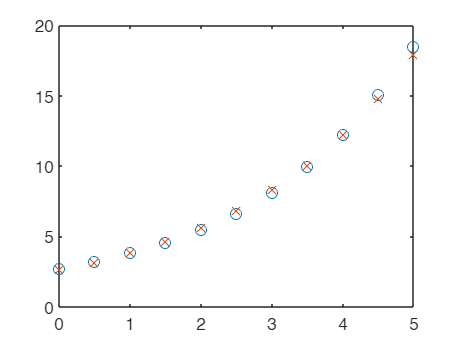

hold off;

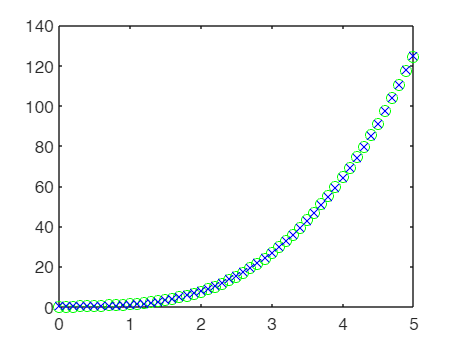

figure;
plot(x,y,'go'); hold on;
plot(x,yfit,'bx')
hold off;

y15 = polyval(p,1.5) % value of y at x = 1.5

y15 = 3.3068

y_true = 1.5^3+ sin(1.5).*cos(1.5)

y_true = 3.4456



% linregrzero (no beta0)
x = [2, 4, 6, 7, 10, 11, 14, 17, 20];
y = [4, 5, 6, 5, 8, 8, 6, 9, 12];
help linregr

  linregr: linear regression curve fitting
    [a, r2] = linregr(x,y): Least squares fit of straight
    line to data by solving the normal equations
  input:
    x = independent variable
    y = dependent variable
  output:
    a = vector of slope, a(1), and intercept, a(2)
    r2 = coefficient of determination
 
  linearization help:
    y = alph * exp(beta*x)
        ln(y) = ln(alph) + beta*x 
            Note: use log() in MATLAB
        [a, r2] = linregr(x, log(y));
        alpha = exp(a(2));
        beta  = a(1);
 
    y = alph * x^beta
        log10(y) = log10(alph) + beta*log10(x)
        [a, r2] = linregr(log10(x), log10(y));
        alpha = 10^(a(2));
        beta  = a(1);
 
    y = alph * x/(beta + x)
        1/y = 1/alph + (beta/alph)*(1/x)
          (linear in 1/x)
        [a, r2] = linregr(1./x, 1./y);
        alpha = 1 / a(2);
        beta  = a(1) / a(2);



a1 = linregrzero(x,y) % just slope if no offset

a1 = 0.6144

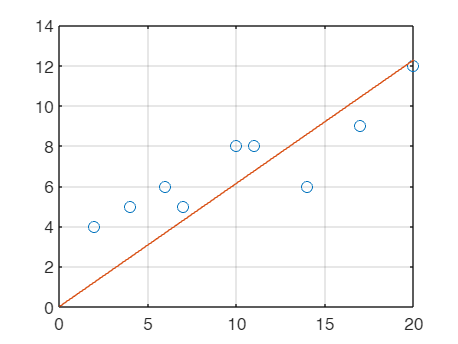

hold off;

coefficients = polyfit(x, y, 1) % used for slopes and intercepts, built-in

coefficients =     0.3678    3.2807


## Ch 15 - Nonlinear Regression

help fitnlm

 fitnlm Create nonlinear regression model by fitting to data.
    NLM = fitnlm(DS,MODELFUN,BETA0) fits the model specified by MODELFUN to
    variables in the dataset/table array DS, and returns the nonlinear model NLM.
    The coefficients are estimated using an iterative procedure starting
    from the initial values in the vector BETA0.
 
    MODELFUN can be either of the following:
 
      1. A function, specified using @, that accepts two arguments, a
         coefficient vector and an array of predictor values, and computes
         a vector of Y values. 
      2. A text string, such as 'y ~ b0+b1*sin(b2*X)', defining the
         response and a mathematical expression for the function. Symbols
         in the function expression that match variable names in the
         dataset/table are taken to be predictors, and the others are
         coefficients to be estimated.
 
    NLM = fitnlm(X,Y,MODELFUN,BETA0) fits a nonlinear regre

help fSSR

 fSSR: f = fSSR(a,xm,ym)
  F = a0*v^a1
  a(1) = a0, a(2) = a1
  sum of squares



help lsqcurvefit

 lsqcurvefit solves non-linear least squares problems.
    lsqcurvefit attempts to solve problems of the form:
    min  sum {(FUN(X,XDATA)-YDATA).^2}  where X, XDATA, YDATA and the values returned
     X                                  by FUN can be vectors or matrices.
    subject to:  A*X  <= B, Aeq*X  = Beq (linear constraints)
                 C(X) <= 0, Ceq(X) = 0  (nonlinear constraints)
                 LB <= X <= UB  (bounds)
 
    lsqcurvefit implements three different algorithms: trust region reflective,
    Levenberg-Marquardt, and Interior-Point. Choose one via the option Algorithm: for
    instance, to  choose Levenberg-Marquardt, set
    OPTIONS = optimoptions('lsqcurvefit','Algorithm','levenberg-marquardt'),
    and then pass OPTIONS to lsqcurvefit.
 
    X = lsqcurvefit(FUN,X0,XDATA,YDATA) starts at X0 and finds coefficients
    X to best fit the nonlinear functions in FUN to the data 

help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
    rsquared -  Coefficient of determination or (unadjusted) R-squared
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit

#### Book Method

 v = [1 2 3 4 5];
 F = [2.1 4.5 7.9 12.6 19.3];

 a = fminsearch(@fSSR, [1 1], [], v, F)

a =     1.3505    1.6404


 %   [1 1] is an initial guess for [a0, a1], [] is a placeholder for options


#### Book Method 2 (Prob not that important)

% Polynomial Regression Using the Normal Equation
%
% This section fits a cubic polynomial to the data using ordinary least
% squares (OLS). Although the model is nonlinear in x (because of x^2 and 
% x^3), it is linear in the coefficients, so it can be solved using linear 
% regression methods.
%
% MODEL:
%     y = a0 + a1*x + a2*x^2 + a3*x^3
%
% DESIGN MATRIX (Z):
%     Each column of Z contains a different power of x:
%         Z = [ 1   x   x.^2   x.^3 ]
%     This allows the polynomial to be written in matrix form:
%         y = Z * a
%     where a = [a0; a1; a2; a3] contains the polynomial coefficients.
%
% NORMAL EQUATION:
%     The least-squares solution minimizes the squared error between the 
%     measured data (y) and the fitted curve (Z*a). The optimal coefficients 
%     are obtained using the normal equation:
%         a = (Z' * Z) \ (Z' * y)
%
% COEFFICIENT OF DETERMINATION (r^2):
%     r^2 measures how well the polynomial fits the data and is computed as:
%         r^2 = 1 - (Sr / St)
%     where Sr is the residual sum of squares and St is the total variation.
%
% After computing the coefficients, the fitted cubic curve can be evaluated
% using:
%     y_fit = a0 + a1*x + a2*x.^2 + a3*x.^3
%
% This method is equivalent to MATLAB's polyfit(x,y,3), but written out
% explicitly to show the underlying linear algebra.
% ======================================================================
x = [1 2 3 4 5]';
y = [2.1 4.5 7.9 12.6 19.3]';

Z = [ones(size(x)) x x.^2 x.^3] % cubic fit

Z =      1     1     1     1
     1     2     4     8
     1     3     9    27
     1     4    16    64
     1     5    25   125


a = (Z'*Z)\(Z'*y)

a =     0.0800
    1.9738
   -0.0429
    0.0833


Sr = sum((y-Z*a).^2)

Sr = 0.0023

r2 = 1-Sr/sum((y-mean(y)).^2)

r2 = 1.0000


% go down the column vector
0.08 + 1.97*x - 0.0429*x.^2 + 0.0833*x.^3

ans =     2.0904
    4.5148
    7.8530
   12.6048
   19.2700


#### Built-In Method (Important)***

% fitnlm
 v = [1 2 3 4 5];
 F = [2.1 4.5 7.9 12.6 19.3];

% Define model: F = a1 * v^a2
modelfun = @(b,x) b(1) * x.^b(2);

beta0 = [1 1];
nlm = fitnlm(v,F,modelfun,beta0)

nlm = Nonlinear regression model:
    y ~ b1*x^b2

Estimated Coefficients:
          Estimate      SE       tStat       pValue  
          ________    _______    ______    __________

    b1     1.3505     0.21788    6.1986     0.0084592
    b2     1.6404     0.10913    15.031    0.00063916


Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 0.617
R-Squared: 0.994,  Adjusted R-Squared 0.992
F-statistic vs. zero model: 809, p-value = 7.95e-05


% lsqcurvefit
model = @(b,x) b(1) * x.^b(2);
b0 = [1 1];
a_fit = lsqcurvefit(model,b0,v,F)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


a_fit =     1.3505    1.6404


#### Polynomial Nonlinear Fit

% Find r^2 for nonlinear model, parabolic fit
v = [10, 20, 30, 40, 50, 60, 70, 80];
F = [25, 70, 380, 550, 610, 1220, 830, 1450];

% Polyfit
help polyfit

 polyfit Fit polynomial to data.
    P = polyfit(X,Y,N) finds the coefficients of a polynomial P(X) of
    degree N that fits the data Y best in a least-squares sense. P is a
    row vector of length N+1 containing the polynomial coefficients in
    descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
 
    [P,S] = polyfit(X,Y,N) returns the polynomial coefficients P and a
    structure S for use with POLYVAL to obtain error estimates for
    predictions.  S contains these fields:
 
          R  -  Triangular R factor (possibly permuted) from a QR
                decomposition of the Vandermonde matrix of X
         df  -  Degrees of freedom
      normr  -  Norm of the residuals
    rsquared -  Coefficient of determination or (unadjusted) R-squared
 
    If the data Y are random, an estimate of the covariance matrix of P is
    (Rinv*Rinv')*normr^2/df, where Rinv is the inverse of R.
 
    [P,S,MU] = polyfit

[p,s] = polyfit(v, F, 2)     % quadratic fit

p =     0.0372   16.1220 -178.4821


s = struct with fields:
           R: [3×3 double]
          df: 5
       normr: 462.3776
    rsquared: 0.8818


F_pred = polyval(p, v)   % predicted values

F_pred = 1.0e+03 *

   -0.0135    0.1588    0.3387    0.5259    0.7206    0.9228    1.1324    1.3494


#### Fitnlm

% Define model: F = a1 * v^a2
modelfun = @(b,x) b(1) + b(2)*x + b(3)*x.^2;

beta0 = [1 1 1];
nlm = fitnlm(v,F,modelfun,beta0)

nlm = Nonlinear regression model:
    y ~ b1 + b2*x + b3*x^2

Estimated Coefficients:
          Estimate      SE        tStat      pValue 
          ________    _______    ________    _______

    b1     -178.48     288.49    -0.61868    0.56322
    b2      16.122     14.708      1.0961      0.323
    b3    0.037202    0.15954     0.23319    0.82486


Number of observations: 8, Error degrees of freedom: 5
Root Mean Squared Error: 207
R-Squared: 0.882,  Adjusted R-Squared 0.834
F-statistic vs. constant model: 18.6, p-value = 0.00481

## Ch 17 - Polynomial Interpolation

help polyint

  polyint: Polynomial interpolation
    yint = polyint(x,y,xx): Uses an (n - 1)-order
    polynomial based on n data points (x, y)
    to determine a value of the dependent variable (yint)
    at a given value of the independent variable, xx.
  input:
    x = independent variable
    y = dependent variable
    xx = value of independent variable at which
        interpolation is calculated
  output:
    yint = interpolated value of dependent variable



help lagrange

--- lagrange not found. Showing help for Lagrange instead. ---

  Lagrange: Lagrange interpolating polynomial
  yint = Lagrange(x,y,xx): Uses an (n order
    Lagrange interpolating polynomial based on n data points
    to determine a value of the dependent variable (yint) at
    a given value of the independent variable, xx.
  input:
    x = independent variable
    y = dependent variable
    xx = value of independent variable at which the
        interpolation is calculated
  output:
    yint = interpolated value of dependent variable



help newtint

--- newtint not found. Showing help for Newtint instead. ---

  Newtint: Newton interpolating polynomial
  yint = Newtint(x,y,xx): Uses an (n order Newton
  interpolating polynomial based on n data points (x, y)
  to determine a value of the dependent variable (yint)
  at a given value of the independent variable, xx.
  input:
    x = independent variable
    y = dependent variable
    xx = value of independent variable at which
            interpolation is calculated
  output:
    yint = interpolated value of dependent variable
        compute the finite divided differences in the form of a
        difference table
  x & y must be same length




x = [1 2 3 4 5 6 7];
y = [3.6 1.8 1.3 0.9 0.72 1.5 0.51429];
xx = 2.7;

% core methods
yint_poly = polyint(x,y,xx)

yint_poly = 1.4001

yint_Newt = Newtint(x,y,xx)

yint_Newt = 1.4001

yint_Lagr = Lagrange(x,y,xx)

yint_Lagr = 1.4001


% there's a bisection one for f = 1.7 i don't fully understand
% could be that we can switch y and x?

% Example 2
x = [1 2 4 8];
fx = @(x) 10*exp(-0.2*x);
y = fx(x);

yint = polyint(x,y,3.275)

yint = 5.1912

ytrue = fx(3.275)

ytrue = 5.1944

et = abs((ytrue - yint) / ytrue)*100

et = 0.0625

#### Inverse Interpolation

Finding the x so we have f(x) = _

% strat:
%   - Go f(x) - f_desired = 0
%   - then use fzero?

% find where f(x) = 6
hold off; fplot(fx, [0 10]); hold on;
plot(x,y);
fx = @(x) fx(x) - 6;
x0 = fzero(fx,mean(x))

x0 = 2.5541

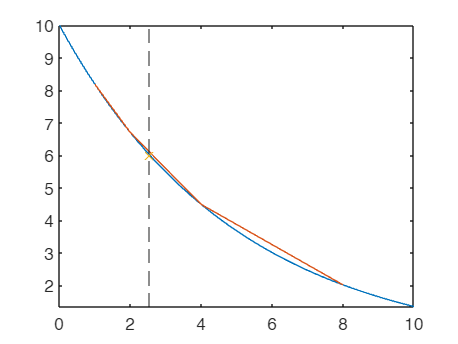

plot(x0, 6,'x'); xline(x0,'--');

% okay cool! (note: i butchered this on the old one)

## Ch 19&20 - Numerical Integration

help integral

 integral  Numerically evaluate integral.
    Q = integral(FUN,A,B) approximates the integral of function FUN from A
    to B using global adaptive quadrature and default error tolerances.
 
    FUN must be a function handle. A and B can be -Inf or Inf. If both are
    finite, they can be complex. If at least one is complex, integral
    approximates the path integral from A to B over a straight line path.
 
    For scalar-valued problems the function Y = FUN(X) must accept a vector
    argument X and return a vector result Y, the integrand function
    evaluated at each element of X. For array-valued problems (see the
    'ArrayValued' option below) FUN must accept a scalar and return an
    array of values.
 
    Q = integral(FUN,A,B,PARAM1,VAL1,PARAM2,VAL2,...) performs the
    integration with specified values of optional parameters. The available
    parameters are
 
    'AbsTol', absolute error tolerance
    'Rel

help romberg

  romberg: Romberg integration quadrature
    [q,ea,iter] = romberg(func,a,b,es,maxit)
    Romberg integration.
  input:
    func = name of function to be integrated
    a, b = integration limits
    es = desired relative error (default = 0.000001%)
    maxit = maximum allowable iterations (default = 30)
    p1,p2,... = additional parameters used by func
  output:
    q = integral estimate
    ea = approximate relative error (%)
    iter = number of iterations



help quadadapt

  Evaluates definite integral of f(x) from a to b
  q = quadadapt(f,a,b,tol)




% integral of velo = position
g = 9.81; m = 68.1; Cd = 0.25;
a = 0; b = 3; n = 10000; tol = 0.1;
v = @(t) sqrt(g*m/Cd)*tanh(sqrt(g*Cd/m)*t);

dist_integ = integral(v,a,b) % best approach for numer integ

dist_integ = 41.9481

dist_trap = trap(v,a,b,n)

dist_trap = 41.9480

dist_romb = romberg(v,a,b,tol)

dist_romb = 41.9479

dist_quad = quadadapt(v,a,b,tol)

dist_quad = 41.9479


d_relTol = integral(v, a, b, 'RelTol', tol) % how to do relative tolerance integral

d_relTol = 41.9481

d_romb = romberg(v,a,b,tol)

d_romb = 41.9479


% Exam
%   Given ftn
%   Use one (likely Romberg) 
%       Compare to Matlab builtin ftn, number of iter
%       Consider step size
%       Consider effect of iterations

help trap 

  trap: composite trapezoidal rule quadrature
    I = trap(func,a,b,n,p1,p2,...):
  composite trapezoidal rule
  input:
    func = function handle to function to be integrated
    a, b = integration limits
    n = number of segments (default = 100)
    p1,p2,... = additional parameters used by func
  output:
    I = integral estimate



help trapuneq

  trapuneq: unequal spaced trapezoidal rule quadrature
    I = trapuneq(x,y):
    Applies the trapezoidal rule to determine the integral
        for n data points (x, y) where x and y must be of the
        same length and x must be monotonically ascending
  input:
    x = vector of independent variables
    y = vector of dependent variables
  output:
    I = integral estimate



help cumtrapz % built in

 cumtrapz Cumulative trapezoidal numerical integration.
    Z = cumtrapz(Y) computes an approximation of the cumulative
    integral of Y via the trapezoidal method (with unit spacing).  To
    compute the integral for spacing different from one, multiply Z by
    the spacing increment.
 
    For vectors, cumtrapz(Y) is a vector containing the cumulative
    integral of Y. For matrices, cumtrapz(Y) is a matrix the same size as
    X with the cumulative integral over each column. For N-D arrays,
    cumtrapz(Y) works along the first non-singleton dimension.
 
    Z = cumtrapz(X,Y) computes the cumulative integral of Y with respect to
    X using trapezoidal integration. X can be a scalar or a vector with the
    same length as the first non-singleton dimension in Y. cumtrapz
    operates along this dimension. If X is a scalar, then cumtrapz(X,Y) is
    


% what happens if discrete points?
x = [0 .12 .22 .32 .36 .4 .44 .54 .64 .7 .8];
y = 0.2+25*x-200*x.^2+675*x.^3-900*x.^4+400*x.^5;

I = trapuneq(x,y)

I = 1.5948

I_trapz = trapz(x,y)

I_trapz = 1.5948

I_cumtrapz = cumtrapz(x,y)

I_cumtrapz =          0    0.0906    0.2213    0.3738    0.4501    0.5407    0.6467    0.9642    1.2987    1.4651    1.5948


## Ch 21 - Numerical Differentiation

help rombdiff

  romberg: Romberg integration quadrature
    [d,ea,iter]=rombdiff(func,x,es,maxit,varargin)
  Romberg differentiation. 
    Implicitly calls dydxnew
  input:
    func = name of function to be integrated
    es = desired relative error (default = 0.000001%)
    maxit = maximum allowable iterations (default = 50)
    p1,p2,... = additional parameters used by func
  output:
    d = integral estimate
    ea = approximate relative error (%)
    iter = number of iterations



help dydxnew

dydxnew is a function.
    d = dydxnew(func, x, n, varargin)



help diff % diff(f,2) = 2nd deriv

 diff Difference and approximate derivative.
    diff(X), for a vector X, is [X(2)-X(1)  X(3)-X(2) ... X(n)-X(n-1)].
    diff(X), for a matrix X, is the matrix of row differences,
       [X(2:n,:) - X(1:n-1,:)].
    diff(X), for an N-D array X, is the difference along the first
       non-singleton dimension of X.
    diff(X,N) is the N-th order difference along the first non-singleton 
       dimension (denote it by DIM). If N >= size(X,DIM), diff takes 
       successive differences along the next non-singleton dimension.
    diff(X,N,DIM) is the Nth difference function along dimension DIM. 
       If N >= size(X,DIM), diff returns an empty array.
 
    Examples:
       h = .001; x = 0:h:pi;
       diff(sin(x.^2))/h is an approximation to 2*cos(x.^2).*x
       diff((1:10).^2) is 3:2:19
 
       If X = [3 7 5
               0 9 2]
       then diff(X,1

            % double(subs(fp_x,x,2) plugs in x = 2 into fp_x

f = @(x) exp(-2*x) - x;

% Calculus by hand
fp = @(x) -2*exp(-2*x) - 1;
fpp = @(x) 4*exp(-2*x);
fp(2)

ans = -1.0366


% diff
syms x
f_x = exp(-2*x) - x;
fp_x = diff(f_x)

$$fp\_x = -2\,{\mathrm{e}}^{-2\,x}-1$$

fpp_x = diff(fp_x)

$$fpp\_x = 4\,{\mathrm{e}}^{-2\,x}$$

% alternatively
fpp_x2 = diff(f_x,2)

$$fpp\_x2 = 4\,{\mathrm{e}}^{-2\,x}$$

double(subs(fp_x, x, 2))

ans = -1.0366


% rombdiff
[d,ea,iter]=rombdiff(f,2) 

d = -1.0366

ea = 7.4050e-07

iter = 4


% Find inflection points, where f2 = 0
f = 1/sqrt(2*pi)*exp(-x^2/2);
f2 = diff(f,2); % 2nd deriv*****
solve(f2==0,x) %******

$$ans = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$


% polyderiv (less useful, but exists
t = 1:100; B = 5*t.^6+20./cos(t);
[p6] = polyfit(t, B, 6);
f = polyval(p6,t);
p5 = -polyder(p6); % deriv, 5th order polynomial
dp5 = polyval(p5,t)./f;

## Chapter 22 - ODEs

help rk4

  [t,y] = rk4(dydt,tspan,y0,h):
  [t,y] = rk4(@dydtsys, tspan, y0, h);
    uses the fourth-order Runge-Kutta method to integrate an ODE
  input:
    dydt = name of the M-file that evaluates the ODE 
    tspan = [ti, tf] where ti and tf = initial and
            final values of independent variable
    y0 = initial value of dependent variable
    h = step size
  output:
    t = vector of independent variable
    y = vector of solution for dependent variable



help dydtsys

dydtsys is a function.
    dy = dydtsys(t, y)



help eulode

  eulode: Euler ODE solver
  [t,y] = eulode(dydt,tspan,y0,h,p1,p2,...):
  uses Euler's method to integrate an ODE
  input:
  dydt = name of the M-file that evaluates the ODE
  tspan = [ti, tf] where ti and tf = initial and
  final values of independent variable
  y0 = initial value of dependent variable
  h = step size
  p1,p2,... = additional parameters used by dydt
  output:
  t = vector of independent variable
  y = vector of solution for dependent variable



help heun 

  [t,y] = Heun(dydt,tspan,y0,h):
    uses the midpoint method to integrate an ODE
  input:
    dydt = name of the M-file that evaluates the ODE 
    tspan = [ti, tf] where ti and tf = initial and
            final values of independent variable
    y0 = initial value of dependent variable
    h = step size
    es = stopping criterion (%)
         optional (default = 0.001)
    maxit = maximum iterations of corrector
         optional (default = 50)
    es = (optional) stopping criterion (%)
    maxit = (optional) maximum allowable iterations
  output:
    t = vector of independent variable
    y = vector of solution for dependent variable



help midpoint

  [t,y] = midpoint(dydt,tspan,y0,h):
    uses the midpoint method to integrate an ODE
  input:
    dydt = name of the M-file that evaluates the ODE 
    tspan = [ti, tf] where ti and tf = initial and
            final values of independent variable
    y0 = initial value of dependent variable
    h = step size
  output:
    t = vector of independent variable
    y = vector of solution for dependent variable

